close all; clear; clc;

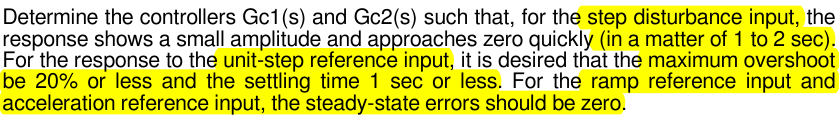

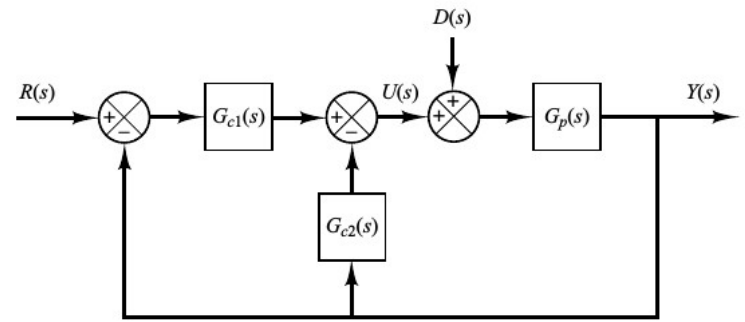

#### Función de transferencia de la planta

syms s
K  = 2;
A  = [1 1];
B  = conv([1 0],conv([1 3],[1 5]));
Gp = tf(K*A,B)

Gp =
 
       2 s + 2
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.



Gp_sym = poly2sym(K*A, s)/poly2sym(B, s)

$$Gp\_sym = \frac{2\,s+2}{s^{3}+8\,s^{2}+15\,s}$$

#### Polos/ceros de la planta

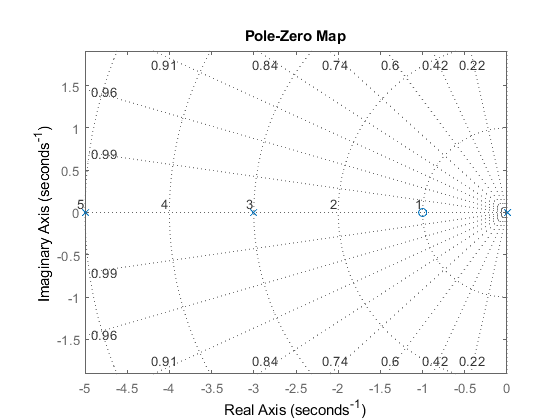

pzmap(Gp); grid on; axis('equal')

Bien, hay que notar que el sistema a lazo abierto tiene un polo en el origen, por lo tanto tiene un integrador puro a la salida.

Por ejemplo podría ser debido a que es una salida de posición obtenida por integración de la velocidad.

# Análisis de las funciones de transferencia

#### Función de transferencia del controlador auxiliar

syms kp kd ki tau_z
Gc_sym_v1 = collect((kp + ki/s + kd*s)/poly2sym(A, s)) % Con el filtro de los ceros como la teoría

$$Gc\_sym\_v1 = \frac{\mathrm{kd}\,s^{2}+\mathrm{kp}\,s+\mathrm{ki}}{s^{2}+s}$$

Gc_sym_v2 = collect(kp + ki/s + kd*s)                  % Sin el filtro de los ceros

$$Gc\_sym\_v2 = \frac{\mathrm{kd}\,s^{2}+\mathrm{kp}\,s+\mathrm{ki}}{s}$$

Gc_sym_v3 = collect((kp + ki/s + kd*s)*(tau_z*s + 1)/poly2sym(A, s), s) % Con el filtro y un cero del controlador

$$Gc\_sym\_v3 = \frac{\left(\mathrm{kd}\,\tau_{z}\right)\,s^{3}+\left(\mathrm{kd}+\mathrm{kp}\,\tau_{z}\right)\,s^{2}+\left(\mathrm{kp}+\mathrm{ki}\,\tau_{z}\right)\,s+\mathrm{ki}}{s^{2}+s}$$

Gc_sym = [Gc_sym_v1, Gc_sym_v2, Gc_sym_v3];

#### Función de transferencia a lazo cerrado desde la perturbación

for i = 1:3
    Gd_sym(i) = collect(Gp_sym/(1 + Gp_sym*Gc_sym(i)), s);
    Gd_sym(i)
end

$$ans = \frac{2\,s^{2}+2\,s}{s^{4}+8\,s^{3}+\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

$$ans = \frac{2\,s^{2}+2\,s}{s^{4}+\left(2\,\mathrm{kd}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

$$ans = \frac{2\,s^{2}+2\,s}{s^{4}+\left(2\,\mathrm{kd}\,\tau_{z}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}}$$

#### Función de transferencia a lazo cerrado desde la referencia

syms Gc1_sym_aux
for i = 1:3
    Gr_sym(i) = collect(Gc1_sym_aux*Gp_sym/(1 + Gp_sym*Gc_sym(i)), s);
    Gr_sym(i)
end

$$ans = \frac{\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym},\mathrm{aux}}\right)\,s^{2}+\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym},\mathrm{aux}}\right)\,s}{s^{4}+8\,s^{3}+\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

$$ans = \frac{\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym},\mathrm{aux}}\right)\,s^{2}+\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym},\mathrm{aux}}\right)\,s}{s^{4}+\left(2\,\mathrm{kd}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

$$ans = \frac{\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym},\mathrm{aux}}\right)\,s^{2}+\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym},\mathrm{aux}}\right)\,s}{s^{4}+\left(2\,\mathrm{kd}\,\tau_{z}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}}$$

#### Función de transferencia de C1

for i = 1:3
    i
   [num, den] = numden(Gr_sym(i));
   w          = coeffs(den, s, 'All');
   w          = sum(w(end-2:end).*s.^[2 1 0])
   num        = simplify(num/Gc1_sym_aux);
   Gc1_sym(i) = w/num;
   Gc1_sym(i)
end

i = 1

$$w = \left(2\,\mathrm{kd}+15\right)\,s^{2}+2\,\mathrm{kp}\,s+2\,\mathrm{ki}$$

$$ans = \frac{\left(2\,\mathrm{kd}+15\right)\,s^{2}+2\,\mathrm{kp}\,s+2\,\mathrm{ki}}{2\,s\,\left(s+1\right)}$$

i = 2

$$w = \left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}$$

$$ans = \frac{\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}{2\,s\,\left(s+1\right)}$$

i = 3

$$w = \left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}$$

$$ans = \frac{\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}}{2\,s\,\left(s+1\right)}$$

#### Función de transferencia de C2

for i = 1:3
    Gc2_sym(i) = collect(Gc_sym(i) - Gc1_sym(i), s);
    Gc2_sym(i) 
end

$$ans = \frac{-15\,s}{2\,s+2}$$

$$ans = \frac{\left(2\,\mathrm{kd}\right)\,s^{2}-15\,s}{2\,s+2}$$

$$ans = \frac{\left(2\,\mathrm{kd}\,\tau_{z}\right)\,s^{2}-15\,s}{2\,s+2}$$

#### Función de transferencia a LC respecto a la ref. final

for i = 1:3
    Gr_sym(i) = collect(subs(Gr_sym(i), Gc1_sym_aux, Gc1_sym(i)), s);
    Gr_sym(i)
end

$$ans = \frac{\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}{s^{4}+8\,s^{3}+\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

$$ans = \frac{\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}{s^{4}+\left(2\,\mathrm{kd}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

$$ans = \frac{\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}}{s^{4}+\left(2\,\mathrm{kd}\,\tau_{z}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}}$$

# Asignación de polos

#### Polinomio característico a LC

for i=1:3
    [num, den] = numden(Gr_sym(i)); 
    denGr(i) = collect(den, s);
    denGr(i)
end

$$ans = s^{4}+8\,s^{3}+\left(2\,\mathrm{kd}+15\right)\,s^{2}+\left(2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}$$

$$ans = s^{4}+\left(2\,\mathrm{kd}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}$$

$$ans = s^{4}+\left(2\,\mathrm{kd}\,\tau_{z}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}\,\tau_{z}+15\right)\,s^{2}+\left(2\,\mathrm{kp}+2\,\mathrm{ki}\,\tau_{z}\right)\,s+2\,\mathrm{ki}$$

#### Polinomio objetivo a LC

syms w1 w2 z1 z2
obj_sym = collect((s^2 + 2*z1*w1*s + w1^2)*(s^2 + 2*z2*w2*s + w2^2), s)

$$obj\_sym = s^{4}+\left(2\,w_{1}\,z_{1}+2\,w_{2}\,z_{2}\right)\,s^{3}+\left({w_{1}}^{2}+4\,z_{1}\,z_{2}\,w_{1}\,w_{2}+{w_{2}}^{2}\right)\,s^{2}+\left(2\,z_{2}\,{w_{1}}^{2}\,w_{2}+2\,z_{1}\,w_{1}\,{w_{2}}^{2}\right)\,s+{w_{1}}^{2}\,{w_{2}}^{2}$$

#### Vector con los valores obtenidos para las tres versiones

w1v = zeros(1, 3);
w2v = zeros(1, 3);
z1v = zeros(1, 3);
z2v = zeros(1, 3);
kpv = zeros(1, 3);
kdv = zeros(1, 3);
kiv = zeros(1, 3);

syms z1 z2 w1 w2

#### Asignación de polos V1

Vamos a dar valores **w1 y z1 dados por las características de desempeño** y luego el valor de **z2 y de las constantes del PID** van a estar determinadas **por las ecuaciones**.

Ts = 1 %sec

Ts = 1

z1 = 0.56 

z1 = 0.5600

z1v(1) = z1;

4/(Ts*z1)   % rad/s

ans = 7.1429

w1     = 6.18

w1 = 6.1800

w1v(1) = w1;
%N       = 0.5;
%w2     = N*w1
w2      = 0.77

w2 = 0.7700

w2v(1)  = w2;

#### Solución del problema

obj             = subs(obj_sym);
denGrCoeffs     = coeffs(denGr(1), s, 'All');
objCoeffs       = coeffs(obj, s, 'All');
eqs             = denGrCoeffs(2:end)==objCoeffs(2:end);

% Reoslver para las variables no asignadas
vars_all = symvar(eqs);
vars_sym = vars_all(arrayfun(@(v) isa(v, 'sym'), vars_all));
sol      = solve(eqs, vars_sym, 'ReturnConditions', true);

for k = 1:length(vars_sym)
    varname = char(vars_sym(k));                  % nombre de la variable como string
    valname = [varname '_val'];                   % nombre nuevo para la variable de salida
    assignin('base', valname, double(sol.(varname)(1)));     % asigna en el workspace base
end
kpv(1) = kp_val;
kdv(1) = kd_val;
kiv(1) = ki_val;
z2v(1) = z2_val;
z2_val

z2_val = 0.7003

syms z1 z2 w1 w2

#### Asignación de polos v2

Vamos a dar valores **w1 y z1 dados por las características de desempeño** y luego el valor de **z2 y de las constantes del PID** van a estar determinadas **por las ecuaciones**.

Ts = 0.8 %sec

Ts = 0.8000

z1 = 1 

z1 = 1

z1v(2) = z1;

w1     = 4/(Ts*z1)   % rad/s

w1 = 5

w1v(2) = w1;
N       = 1.9;
w2     = N*w1

w2 = 9.5000

w2v(2) = w2;

#### Solución del problema

obj             = subs(obj_sym);
denGrCoeffs     = coeffs(denGr(2), s, 'All');
objCoeffs       = coeffs(obj, s, 'All');
eqs             = denGrCoeffs(2:end)==objCoeffs(2:end);

% Reoslver para las variables no asignadas
vars_all = symvar(eqs);
vars_sym = vars_all(arrayfun(@(v) isa(v, 'sym'), vars_all));
sol      = solve(eqs, vars_sym, 'ReturnConditions', true);

for k = 1:length(vars_sym)
    varname = char(vars_sym(k));                  % nombre de la variable como string
    valname = [varname '_val'];                   % nombre nuevo para la variable de salida
    assignin('base', valname, double(sol.(varname)(1)));     % asigna en el workspace base
end

kpv(2) = kp_val;
kdv(2) = kd_val;
kiv(2) = ki_val;
z2v(2) = z2_val;
z2_val

z2_val = 4.7763

syms z1 z2 w1 w2

**Asignación de polos v3**

En este caso hay que determinar 4 variables a partir de cuatro incógnitas y no solamente 3 como antes, dado que hay que determinar el valor de $\tau_z$ además de las constantes del PID. Por lo tanto podemos asignar directamente los dos pares de polos complejos conjugados y luego determinar todas las constante.

Ts      = 2.45 %sec

Ts = 2.4500

z1      = 0.88

z1 = 0.8800

z1v(3) = z1;
w1        = 4/(Ts*z1)   % rad/s

w1 = 1.8553

w1v(3) = w1;
N           = 9.8;
w2          = N*w1;
w2v(3)      = w2;
z2          = 0.98

z2 = 0.9800

z2v(3) = z2;

#### Solución del problema

obj             = subs(obj_sym);
denGrCoeffs     = coeffs(denGr(3), s, 'All');
objCoeffs       = coeffs(obj, s, 'All');
eqs             = denGrCoeffs(2:end)==objCoeffs(2:end);

% Reoslver para las variables no asignadas
vars_all = symvar(eqs);
vars_sym = vars_all(arrayfun(@(v) isa(v, 'sym'), vars_all));
sol      = solve(eqs, vars_sym, 'ReturnConditions', true);

for k = 1:length(vars_sym)
    varname = char(vars_sym(k));                  % nombre de la variable como string
    valname = [varname '_val'];                   % nombre nuevo para la variable de salida
    assignin('base', valname, double(sol.(varname)(1)));     % asigna en el workspace base
end

kpv(3) = kp_val;
kdv(3) = kd_val;
kiv(3) = ki_val;

#### Soluciones obtenidas

kpv

kpv =    22.2891  457.5000  548.3930


kdv

kdv =    15.5733   46.3750  166.9351


kiv

kiv = 	1.0e+03 *

    0.0094    1.1281    0.5689


#### Función de transferencia del sistema a LC respecto a la ref

for i = 1:3
    if i == 3
        aux = subs(Gr_sym(i), [kp, kd, ki, tau_z], [kpv(i), kdv(i), kiv(i), tau_z_val]);
    else
        aux = subs(Gr_sym(i), [kp, kd, ki], [kpv(i), kdv(i), kiv(i)]);
    end
    [num, den] = numden(aux);
    num        = sym2poly(num);
    den        = sym2poly(den);
    Gr(i)      = tf(num, den);
    Gr(i)
end

ans =
 
                 1.299e16 s^2 + 1.255e16 s + 5.268e15
  ------------------------------------------------------------------
  2.815e14 s^4 + 2.252e15 s^3 + 1.299e16 s^2 + 1.255e16 s + 5.268e15
 
Continuous-time transfer function.


ans =
 
           4091 s^2 + 12685 s + 9025
  -------------------------------------------
  4 s^4 + 403 s^3 + 4091 s^2 + 12685 s + 9025
 
Continuous-time transfer function.


ans =
 
                 1.427e32 s^2 + 3.81e32 s + 3.606e32
  -----------------------------------------------------------------
  3.169e29 s^4 + 1.233e31 s^3 + 1.427e32 s^2 + 3.81e32 s + 3.606e32
 
Continuous-time transfer function.



#### Función de transferencia del sistema a LC respecto de la perturbación

for i = 1:3
    if i == 3
        aux = subs(Gd_sym(i), [kp, kd, ki, tau_z], [kpv(i), kdv(i), kiv(i), tau_z_val]);
    else
        aux = subs(Gd_sym(i), [kp, kd, ki], [kpv(i), kdv(i), kiv(i)]);
    end
    [num, den] = numden(aux);
    num        = sym2poly(num);
    den        = sym2poly(den);
    Gd(i)      = tf(num, den);
    Gd(i)
end

ans =
 
                      5.629e14 s^2 + 5.629e14 s
  ------------------------------------------------------------------
  2.815e14 s^4 + 2.252e15 s^3 + 1.299e16 s^2 + 1.255e16 s + 5.268e15
 
Continuous-time transfer function.


ans =
 
                  8 s^2 + 8 s
  -------------------------------------------
  4 s^4 + 403 s^3 + 4091 s^2 + 12685 s + 9025
 
Continuous-time transfer function.


ans =
 
                      6.338e29 s^2 + 6.338e29 s
  -----------------------------------------------------------------
  3.169e29 s^4 + 1.233e31 s^3 + 1.427e32 s^2 + 3.81e32 s + 3.606e32
 
Continuous-time transfer function.



#### Función de transferencia del sistema a LC respecto de la referencia hacia U

for i = 1:3
    Gru(i)         = Gr(i)/Gp;
    Gru(i)
end

ans =
 
       1.299e16 s^5 + 1.165e17 s^4 + 3.005e17 s^3 + 2.304e17 s^2 + 7.901e16 s
  ---------------------------------------------------------------------------------
  5.629e14 s^5 + 5.067e15 s^4 + 3.048e16 s^3 + 5.107e16 s^2 + 3.563e16 s + 1.054e16
 
Continuous-time transfer function.


ans =
 
  4091 s^5 + 45413 s^4 + 171870 s^3 + 262475 s^2 + 135375 s
  ---------------------------------------------------------
  8 s^5 + 814 s^4 + 8988 s^3 + 33552 s^2 + 43420 s + 18050
 
Continuous-time transfer function.


ans =
 
       1.427e32 s^5 + 1.523e33 s^4 + 5.549e33 s^3 + 8.599e33 s^2 + 5.409e33 s
  ---------------------------------------------------------------------------------
  6.338e29 s^5 + 2.529e31 s^4 + 3.101e32 s^3 + 1.047e33 s^2 + 1.483e33 s + 7.212e32
 
Continuous-time transfer function.



#### Función de transferencia del sistema a LC respecto de la perturbación hacia U

for i = 1:3
    Gdu(i)         = Gd(i)/Gp;
    Gdu(i)
end

ans =
 
              5.629e14 s^5 + 5.067e15 s^4 + 1.295e16 s^3 + 8.444e15 s^2
  ---------------------------------------------------------------------------------
  5.629e14 s^5 + 5.067e15 s^4 + 3.048e16 s^3 + 5.107e16 s^2 + 3.563e16 s + 1.054e16
 
Continuous-time transfer function.


ans =
 
             8 s^5 + 72 s^4 + 184 s^3 + 120 s^2
  --------------------------------------------------------
  8 s^5 + 814 s^4 + 8988 s^3 + 33552 s^2 + 43420 s + 18050
 
Continuous-time transfer function.


ans =
 
              6.338e29 s^5 + 5.704e30 s^4 + 1.458e31 s^3 + 9.507e30 s^2
  ---------------------------------------------------------------------------------
  6.338e29 s^5 + 2.529e31 s^4 + 3.101e32 s^3 + 1.047e33 s^2 + 1.483e33 s + 7.212e32
 
Continuous-time transfer function.



% Frecuencias y amortiguamientos
w1v

w1v =     6.1800    5.0000    1.8553


w2v

w2v =     0.7000    9.5000   18.1818


z1v

z1v =     0.5600    1.0000    0.8800


z2v

z2v =     0.7703    4.7763    0.9800


# Mapas de polos ceros.

#### Funciones hacia Y

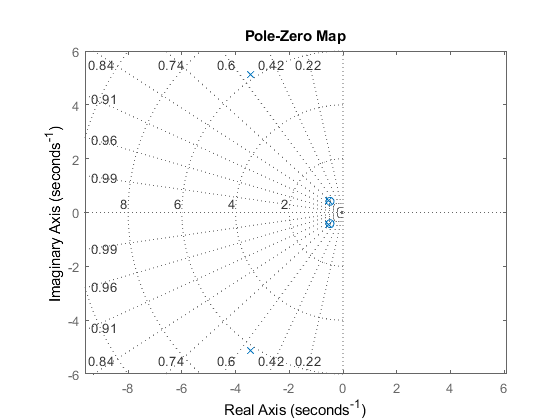

pzmap(Gr(1)); grid on; axis('equal');

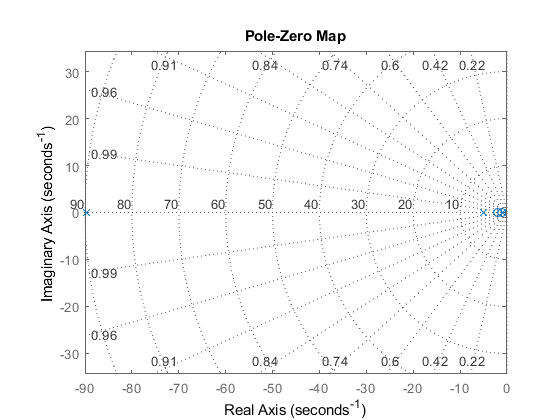

pzmap(Gr(2)); grid on; axis('equal');

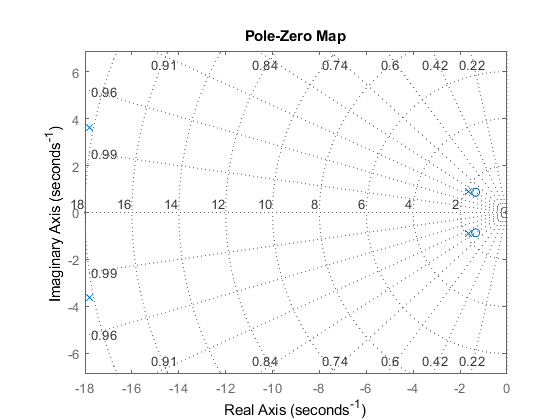

pzmap(Gr(3)); grid on; axis('equal');

#### Funciones de transferencia hacia U

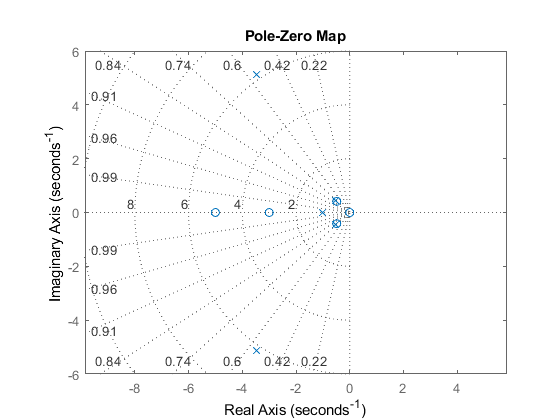

pzmap(Gru(1)); grid on; axis('equal');

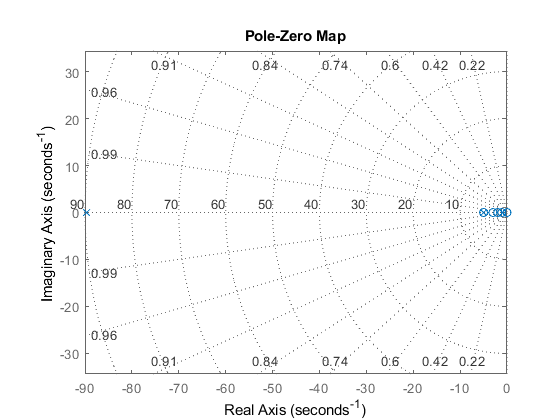

pzmap(Gru(2)); grid on; axis('equal');

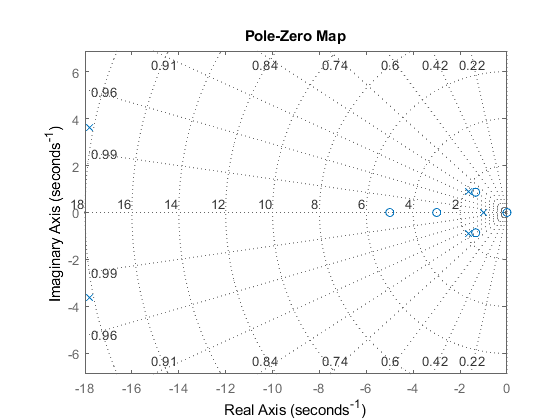

pzmap(Gru(3)); grid on; axis('equal');

# Respuestas

#### Respuesta al escalón de perturbación

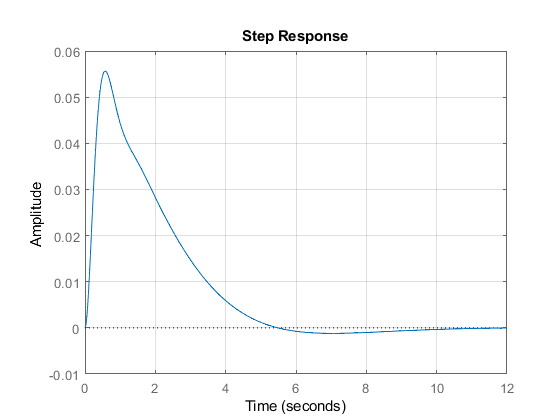

step(Gd(1)); grid on;

stepinfo(Gd(1))

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 7.6151
     SettlingMin: -0.0012
     SettlingMax: 0.0557
       Overshoot: Inf
      Undershoot: Inf
            Peak: 0.0557
        PeakTime: 0.5855


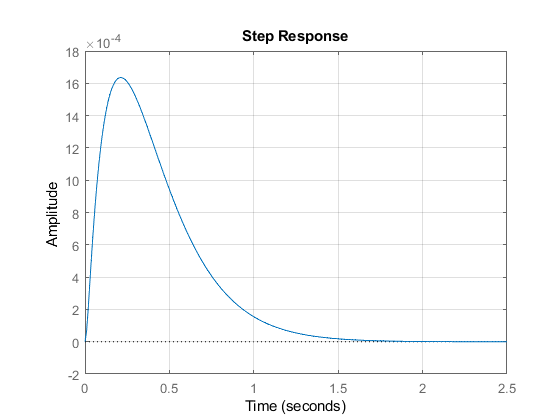

step(Gd(2)); grid on;

stepinfo(Gd(2))

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 1.3652
     SettlingMin: -4.1588e-07
     SettlingMax: 0.0016
       Overshoot: Inf
      Undershoot: Inf
            Peak: 0.0016
        PeakTime: 0.2118


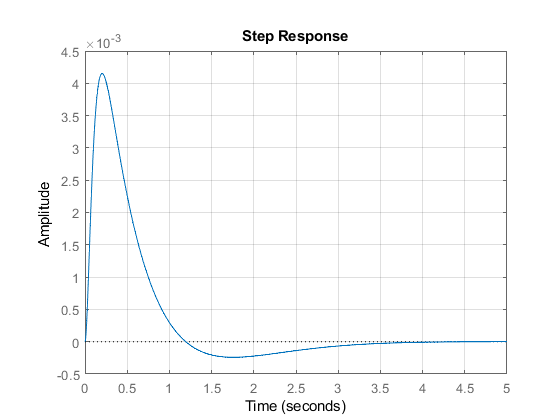

step(Gd(3)); grid on;

stepinfo(Gd(3))

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 2.8621
     SettlingMin: -2.4149e-04
     SettlingMax: 0.0042
       Overshoot: Inf
      Undershoot: Inf
            Peak: 0.0042
        PeakTime: 0.2016


#### Respuesta al escalón de referencia

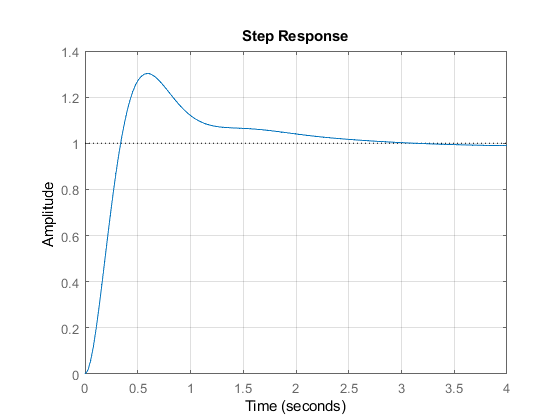

step(Gr(1)); grid on;

stepinfo(Gr(1))

ans = struct with fields:
        RiseTime: 0.2318
    SettlingTime: 2.4162
     SettlingMin: 0.9496
     SettlingMax: 1.3024
       Overshoot: 30.2381
      Undershoot: 0
            Peak: 1.3024
        PeakTime: 0.5855


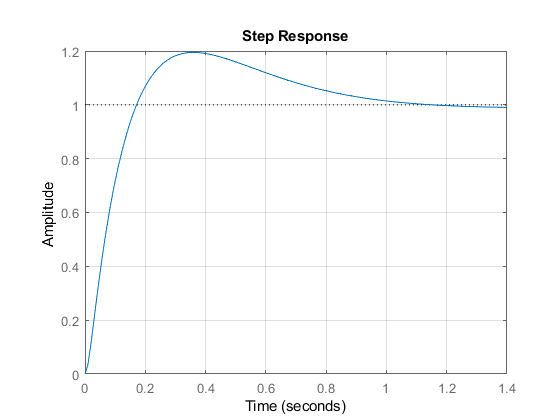

step(Gr(2)); grid on;

stepinfo(Gr(2))

ans = struct with fields:
        RiseTime: 0.1220
    SettlingTime: 0.9597
     SettlingMin: 0.9263
     SettlingMax: 1.1947
       Overshoot: 19.4697
      Undershoot: 0
            Peak: 1.1947
        PeakTime: 0.3592


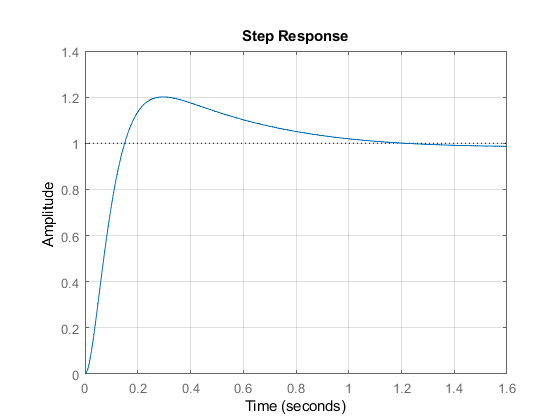

step(Gr(3)); grid on;

stepinfo(Gr(3))

ans = struct with fields:
        RiseTime: 0.1037
    SettlingTime: 0.9947
     SettlingMin: 0.9061
     SettlingMax: 1.2009
       Overshoot: 20.0892
      Undershoot: 0
            Peak: 1.2009
        PeakTime: 0.2946


#### Respuesta a la rampa de referencia

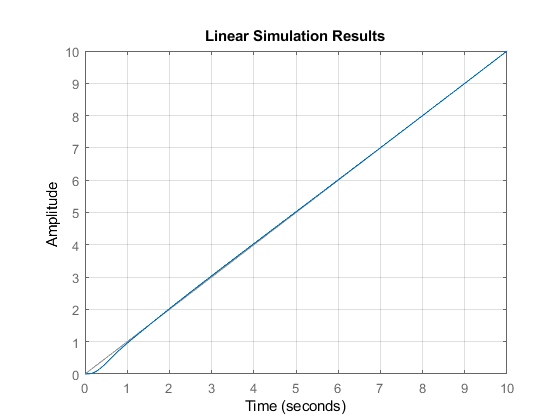

t    = 0:0.01:10;
ramp = t;
lsim(Gr(1), ramp, t); grid on;

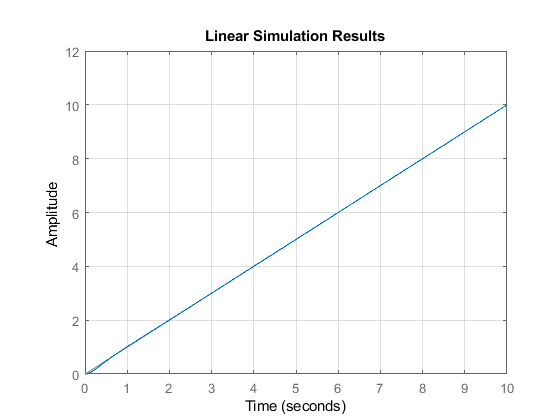

lsim(Gr(2), ramp, t); grid on;

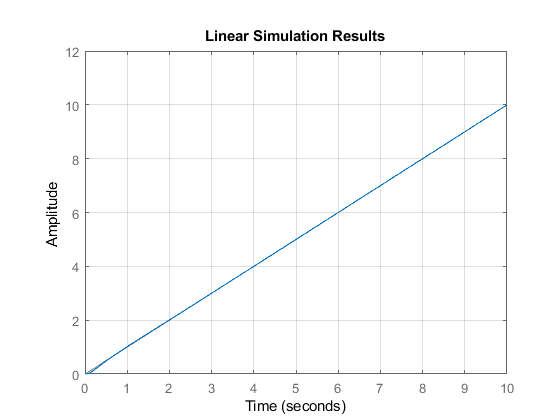

lsim(Gr(3), ramp, t); grid on;

#### Respuesta a la parábola de referencia

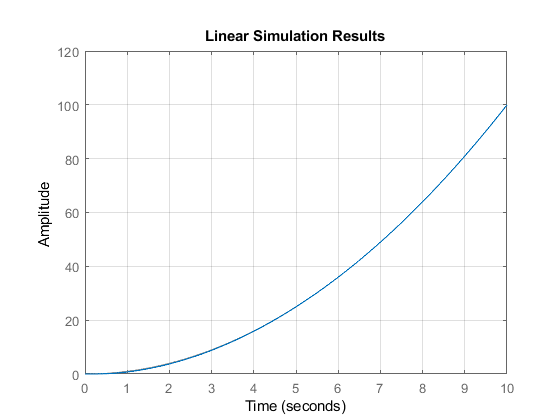

parab = t.^2;
lsim(Gr(1), parab, t); grid on;

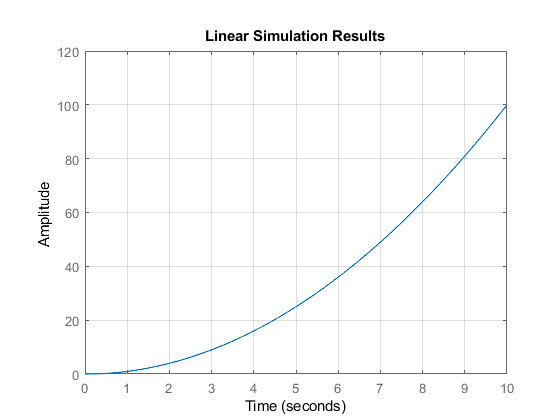

lsim(Gr(2), parab, t); grid on;

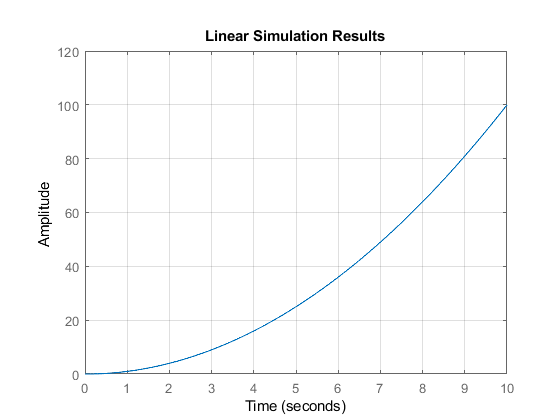

lsim(Gr(3), parab, t); grid on;

# Acciones de control

#### Acciones de control para el escalón de referencia

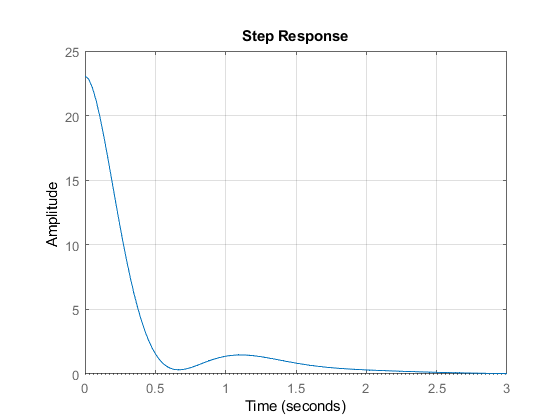

step(Gru(1)); grid on;

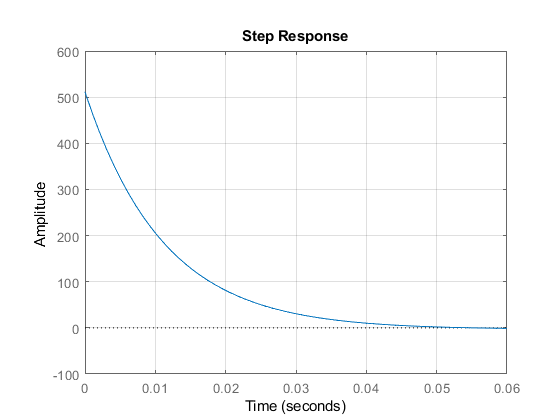

step(Gru(2)); grid on;

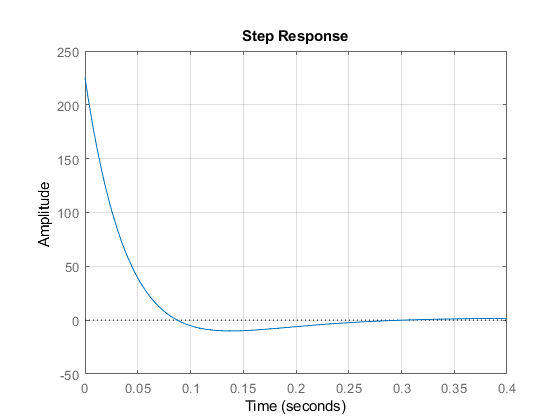

step(Gru(3)); grid on;

#### Acciones de control para el escalón de perturbación

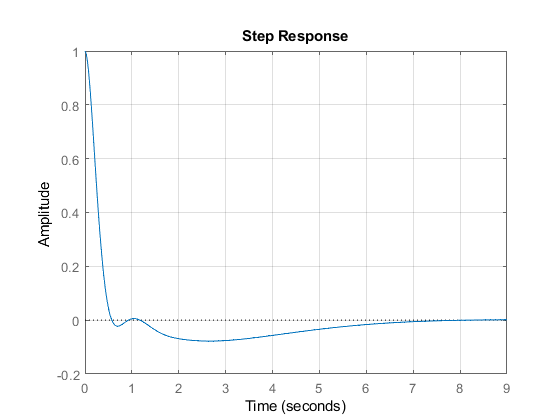

step(Gdu(1)); grid on;

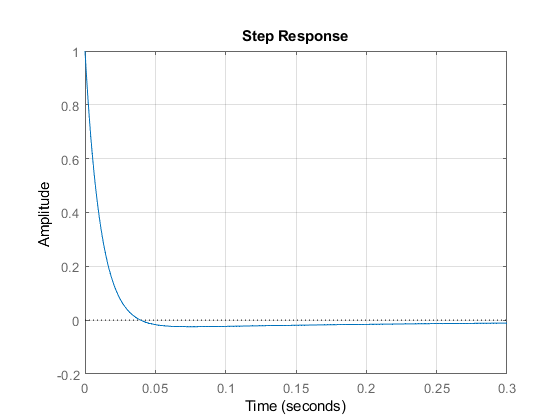

step(Gdu(2)); grid on;

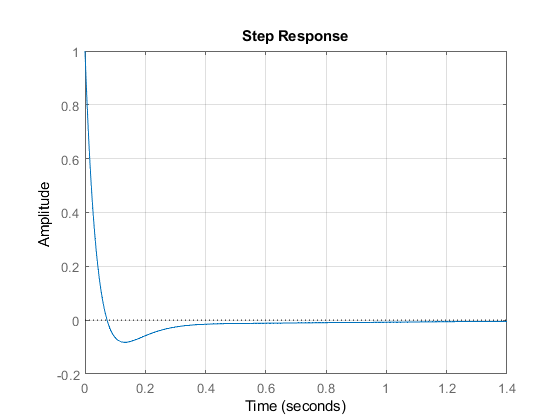

step(Gdu(3)); grid on;

#### Acciones de control para la rampa de referencia

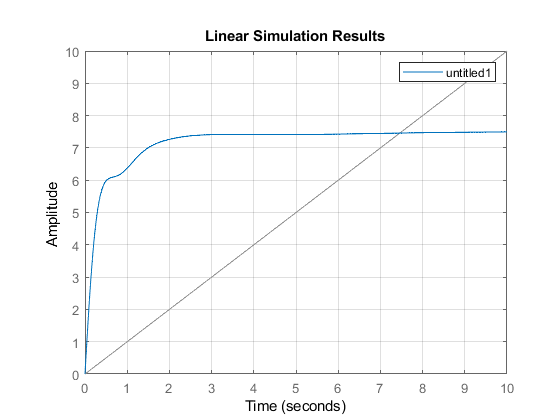

lsim(Gru(1), ramp, t); grid on;legend;

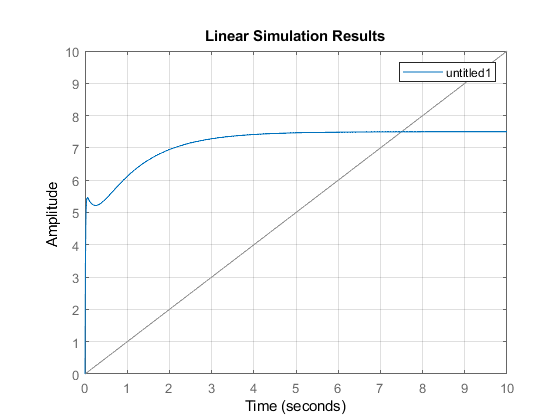

lsim(Gru(2), ramp, t); grid on;legend;

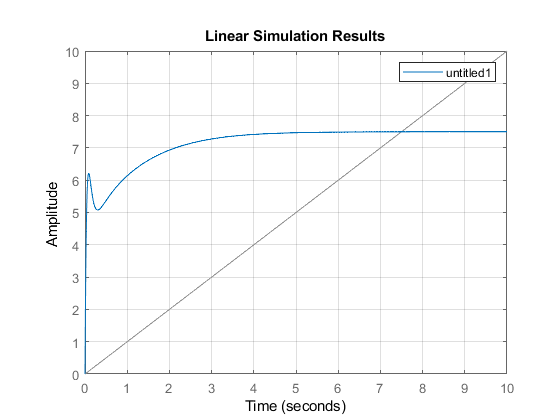

lsim(Gru(3), ramp, t); grid on;legend;

#### Acciones de control para la parábola de referencia

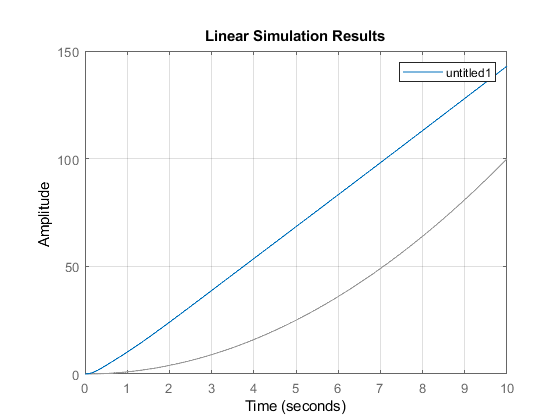

lsim(Gru(1), parab, t); grid on; legend;

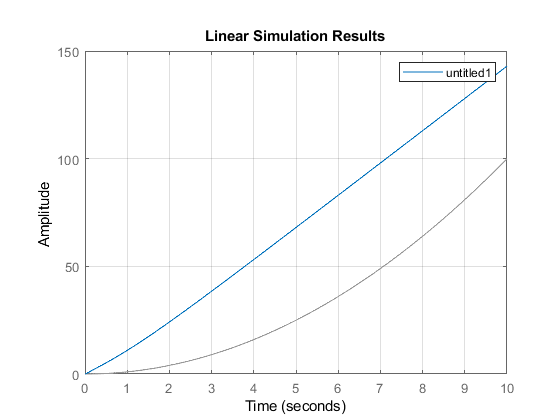

lsim(Gru(2), parab, t); grid on; legend;

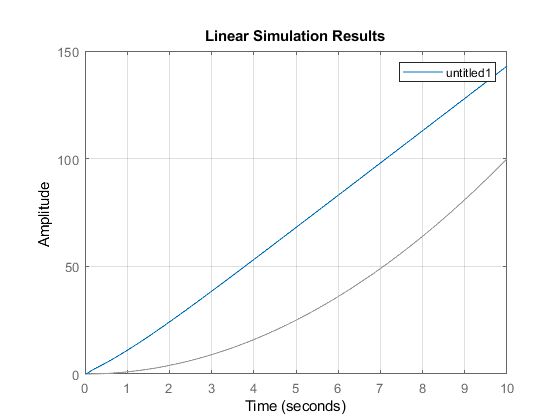

lsim(Gru(3), parab, t); grid on; legend;